# Test script for basic TANDEM-STRAIGHT analysis and synthesis

clear
%   Please use this in "cell mode"

## Initialize conditions        %条件を初期化

original_name = '';

directoryBase = [pwd '/'];
filename_save = 'sample3-2-1';
filename_save2 = filename_save;

% % directoryBase = './強調音声/強調音声＿動的＿phoneme/mode_1/';                        %処理する音声の場所
% % filename_save = '強調音声_動的_phoneme［n=48, weight=5, range=2500-3500, mode=1］【sample1-2-1】';
% % filename_save2 = '強調音声\_動的\_phoneme［n=48, weight=5, range=2500-3500, mode=1］【sample1-2-1】';
% % original_name = 'sample1-2-1';

fileName = [filename_save '.wav'];

if isempty(original_name) == 1                  %元音声の場合
    fileName_lab = [filename_save '_lab.txt'];
else                                            %強調音声の場合
    fileName_lab = [original_name '_lab.txt'];
end

label = sploadlabel(fileName_lab, 'sec');

noisy = 0; % If the speech material consists of low frequency noise, set this vaviable 1;
plotFigures = 1; % If you do not need plots, set this variable 0.

## Read speech data from a file   %ファイルから音声データを読み取る

[x,fs] = audioread([directoryBase fileName]);

x = x(:,1); %   Make sure it is a comum vector.
soundsc(x,fs) % Playback sound

## Extract source information    %ソース情報を抽出する

## Extract spectral informatiopn    %スペクトル情報を抽出する

filename_straight = ['STRAIGHT_ver2【' filename_save '】.mat'];

%matファイルの有無による処理
if (exist(filename_straight,'file') == 0)
    disp('matファイルが見つかりませんでした。');
    
   [f, rc, q, fs] = getstraight_ver3(x, fs, noisy);           %STRAIGHTスペクトル抽出部分の関数化
    save(filename_straight, 'f', 'rc', 'q', 'fs');            %STRAIGHTスペクトルのmatファイルを作成
else
    disp('matファイルが見つかりました。');
    file = load(filename_straight);
    
    f = file.f;
    fs = file.fs;
    rc = file.rc;
    q = file.q;
end

matファイルが見つかりませんでした。


経過時間は 6.797062 秒です。
経過時間は 0.120374 秒です。
経過時間は 1.924607 秒です。
経過時間は 4.441173 秒です。


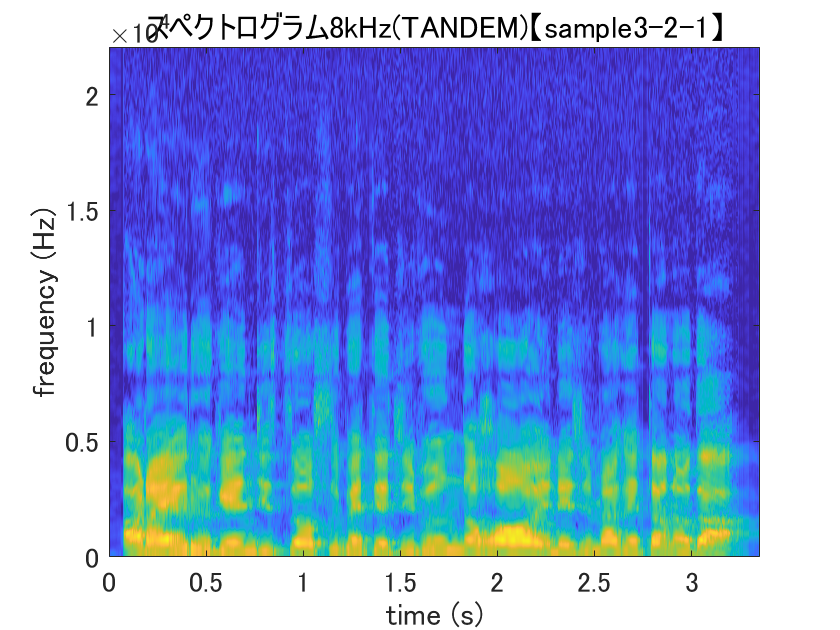

sgramSTRAIGHT = 10*log10(f.spectrogramSTRAIGHT);
maxLevel = max(max(sgramSTRAIGHT));
figure;
imagesc([0 f.temporalPositions(end)],[0 fs/2],max(maxLevel-80,sgramSTRAIGHT));
axis('xy')
set(gca,'fontsize',14);
xlabel('time (s)')
ylabel('frequency (Hz)');
% str = ['スペクトログラム(TANDEM)【' filename_save '】'];          %動的にファイル名を作成
str = ['スペクトログラム8kHz(TANDEM)【' filename_save '】'];          %動的にファイル名を作成
title(str);                                            %タイトル

% xlim([0 4.0]);                                         %x軸の値の範囲
% ylim([0 8000]);                                        %y軸の値の範囲
% print(str, '-dmeta');                                  %emf形式(拡張メタファイル)として保存

## 振幅スペクトルに変換

f0raw = rc.f0';
n3sgram = sqrt(f.spectrogramSTRAIGHT);    %パワースペクトルを振幅スペクトルに変更

% save(filename_save, 'f0raw', 'fs', 'n3sgram');      %matファイルの作成（動的特徴量用）

## 長時間平均スペクトル

str = '他【sample3-2-1】'

ans = 'FontSize'

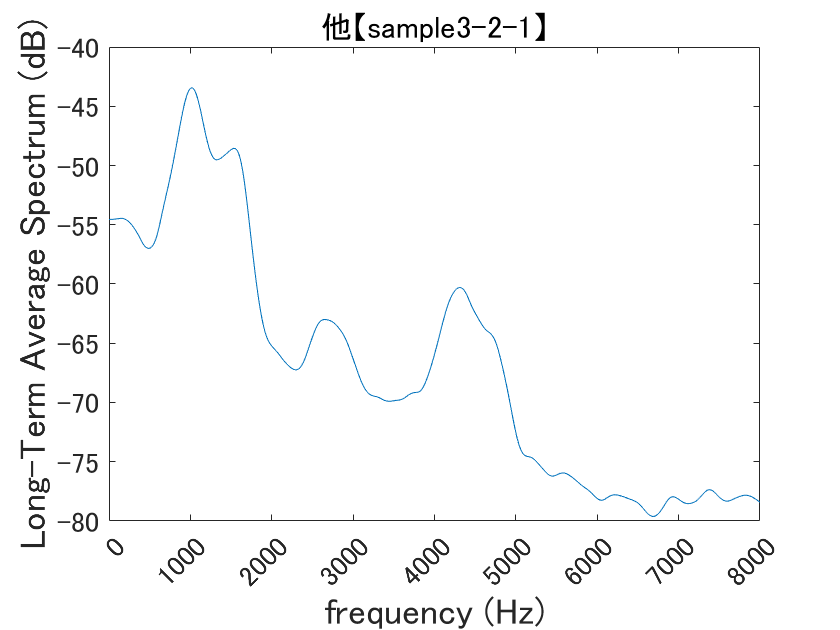

%%母音・子音・他に分割(長時間平均スペクトル)
column_len = size(f.spectrogramSTRAIGHT, 2);      %列
label_len = size(label, 2);         %ラベルの列
vowel = {'a','i','u','e','o','o:'};      %母音

pointPeriod = f.framePeriod * 1000;                     %STRAIGHTスペクトルの間隔（例：1ms）を秒に変換

column_len_other = 0;
column_len_vowel = 0;
column_len_consonant = 0;

%【他の部分(1)】
%音素開始前
time_start = label(1).time;                             %音素の開始時間
time_stop = label(2).time;     %音素の終了時間
column_start = round(time_start*pointPeriod)+1;         %音素の開始時間から列を求める（「pointPeriod」秒に1点）
column_stop = round(time_stop*pointPeriod);             %音素の終了時間から列を求める（「pointPeriod」秒に1点）
for ii = 1:1:column_start-1                               %1つ目の音素が始まる前の部分を代入
    f.spectrogramSTRAIGHT_other(:, ii) = f.spectrogramSTRAIGHT(:, ii);
    column_len_other = column_len_other + 1;
end

%【母音・子音の部分】
for number = 1:1:label_len-1
    select = strcmp(label(number).phoneme, vowel);
%     select_sum = sum(select,'all');         %母音:1、子音:0
    select_sum = sum(select); 
    time_start = label(number).time;        %音素の開始時間
    time_stop = label(number + 1).time;     %音素の終了時間
    column_start = round(time_start*pointPeriod)+1;     %音素の開始時間から列を求める（「pointPeriod」秒に1点）
    column_stop = round(time_stop*pointPeriod);         %音素の終了時間から列を求める（「pointPeriod」秒に1点）
    
    if select_sum == 1      %【母音の部分】
        for ii = column_start:1:column_stop
            f.spectrogramSTRAIGHT_vowel(:, ii) = f.spectrogramSTRAIGHT(:, ii);
            column_len_vowel = column_len_vowel + 1;
        end
    else                    %【子音の部分】
        for ii = column_start:1:column_stop
            f.spectrogramSTRAIGHT_consonant(:, ii) = f.spectrogramSTRAIGHT(:, ii);
            column_len_consonant = column_len_consonant + 1;
        end
    end   
end

%【他の部分(2)】
%音素終了後
for ii = column_stop+1:1:column_len
    f.spectrogramSTRAIGHT_other(:, ii) = f.spectrogramSTRAIGHT(:, ii);
    column_len_other = column_len_other + 1;
end

%%長時間平均スペクトルの算出
%【他の部分】
if column_len_other ~= 0
    ltas_other = sum(f.spectrogramSTRAIGHT_other, 2) ./ column_len_other;    %行方向の平均
    fftl_other = (length(ltas_other)-1)*2;                         %fftlを新たに定義
    x_other = ((0:fftl_other/2)*fs/fftl_other)';                               %横軸をHzで表示
    ltas_decibel_other = 10 * log10(ltas_other);             %dB値に変換
%     plot(x_other, ltas_other); 
    plot(x_other, ltas_decibel_other); 
    set(gca,'FontSize',14);
    xticks(0:1000:8000);
    xtickangle(45);
    xlabel('frequency (Hz)', 'fontsize', 18);
    ylabel('Long-Term Average Spectrum (dB)', 'fontsize', 18);
    str = ['他【' filename_save '】'],'FontSize',14; 
    title(str);                                            %タイトル                       
    xlim([0 8000]);
    str = ['長時間平均スペクトル(dB)8kHz(他)【' filename_save '】'];
    % print(str, '-dmeta');                                  %emf形式(拡張メタファイル)として保存
end

str = '母音　女性話者＿文＿通りにくい声'

ans = 'FontSize'

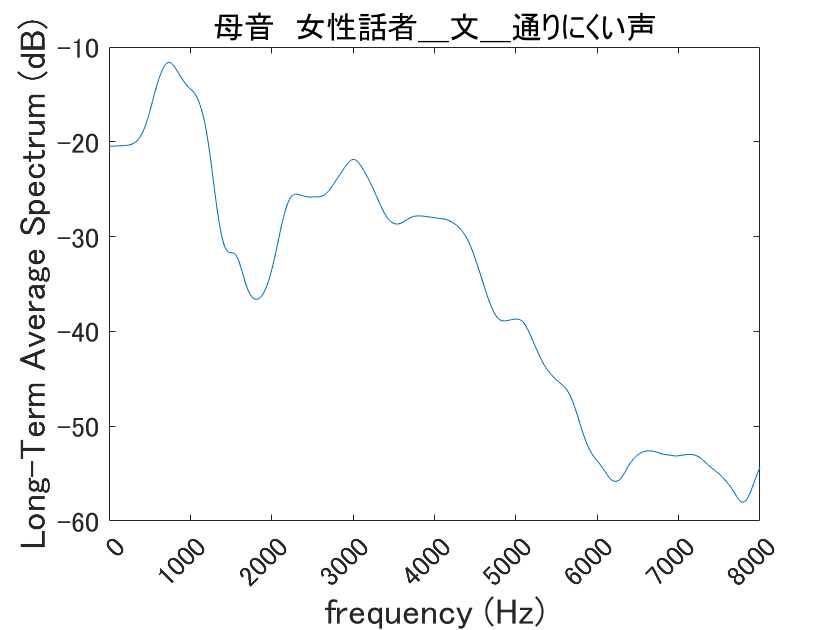

    
%【母音部分】
if column_len_vowel ~= 0
    ltas_vowel = sum(f.spectrogramSTRAIGHT_vowel, 2) ./ column_len_vowel;    %行方向の平均
    fftl_vowel = (length(ltas_vowel)-1)*2;                         %fftlを新たに定義
    x_vowel = ((0:fftl_vowel/2)*fs/fftl_vowel)';                               %横軸をHzで表示
    ltas_decibel_vowel = 10 * log10(ltas_vowel);             %dB値に変換
%     plot(x_vowel, ltas_vowel);
    plot(x_vowel, ltas_decibel_vowel); 
    set(gca,'FontSize',14);
    xticks(0:1000:8000);
    xtickangle(45);
    xlabel('frequency (Hz)', 'fontsize', 18);
    ylabel('Long-Term Average Spectrum (dB)', 'fontsize', 18);
%     str = ['母音【' filename_save '】'],'FontSize',14; 
    str = '母音　女性話者＿文＿通りにくい声','FontSize',14;
    title(str);                                            %タイトル                       
    xlim([0 8000]);
%     ylim([-60 -10]);
    str = ['長時間平均スペクトル(dB)8kHz(母音)【' filename_save '】'];
%     print(str, '-dmeta');                                  %emf形式(拡張メタファイル)として保存
end

str = '子音　女性話者＿文＿通りにくい声'

ans = 'FontSize'

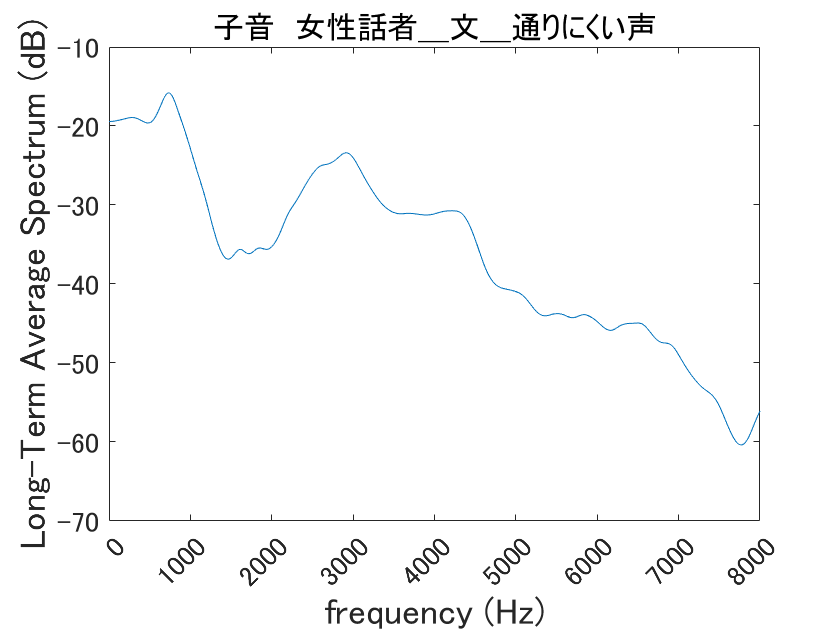

    
%【子音部分】
if  column_len_consonant ~= 0
    ltas_consonant = sum(f.spectrogramSTRAIGHT_consonant, 2) ./ column_len_consonant;    %行方向の平均
    fftl_consonant = (length(ltas_consonant)-1)*2;                         %fftlを新たに定義
    x_consonant = ((0:fftl_consonant/2)*fs/fftl_consonant)';                               %横軸をHzで表示
    ltas_decibel_consonant = 10 * log10(ltas_consonant);             %dB値に変換
    % plot(x_consonant, ltas_consonant); 
    plot(x_consonant, ltas_decibel_consonant); 
    set(gca,'FontSize',14);
    xticks(0:1000:8000);
    xtickangle(45);
    xlabel('frequency (Hz)', 'fontsize', 18);
    ylabel('Long-Term Average Spectrum (dB)', 'fontsize', 18);
    str = ['子音　女性話者＿文＿通りにくい声'],'FontSize',14; 
    title(str);                                            %タイトル                       
    xlim([0 8000]);
%     ylim([-60 -10]);
    str = ['長時間平均スペクトル(dB)8kHz(子音)【' filename_save '】'];
%     print(str, '-dmeta');                                  %emf形式(拡張メタファイル)として保存
end


%【全体】
column_size = size(f.spectrogramSTRAIGHT, 2);      %列の大きさ
ltas = sum(f.spectrogramSTRAIGHT, 2) ./ column_size;    %行方向の平均
fftl = (length(ltas)-1)*2;                         %fftlを新たに定義
x = ((0:fftl/2)*fs/fftl)';                         %横軸をHzで表示
ltas_decibel = 10 * log10(ltas);                   %dB値に変換
% plot(x, ltas); 
plot(x, ltas_decibel); 
set(gca,'FontSize',14);
xticks(0:1000:8000);
xtickangle(45);
xlabel('frequency (Hz)', 'fontsize', 18);
ylabel('Long-Term Average Spectrum (dB)', 'fontsize', 18);
str = ['全体【' filename_save '】'],'FontSize',14; 

str = '全体【sample3-2-1】'

ans = 'FontSize'

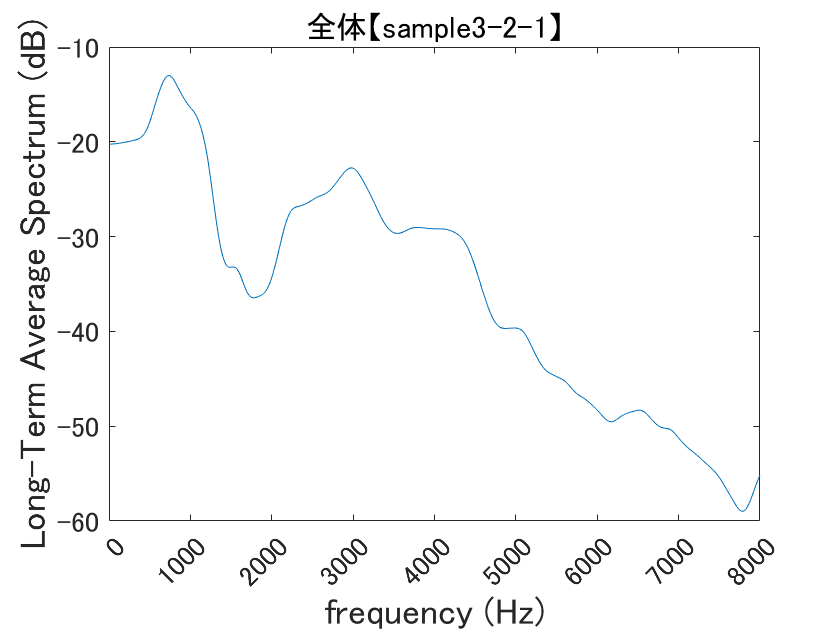

title(str);                                            %タイトル                       
xlim([0 8000]);

str = ['長時間平均スペクトル(dB)8kHz(全体)【' filename_save '】'];
% print(str, '-dmeta');                                  %emf形式(拡張メタファイル)として保存